x = [1, 3, 4, 5, 7];

y = [2, 0, -1, 3, 4];

xcol1=[1,1,1,1,1]';
xcol2 = x';

A = [xcol1 xcol2];
size(A)

ans =      5     2


size(y')

ans =      5     1



b=y';

%format rational
 xhat = inv(A'*A)*A'*b;
 xhat

xhat =    -0.2000
    0.4500


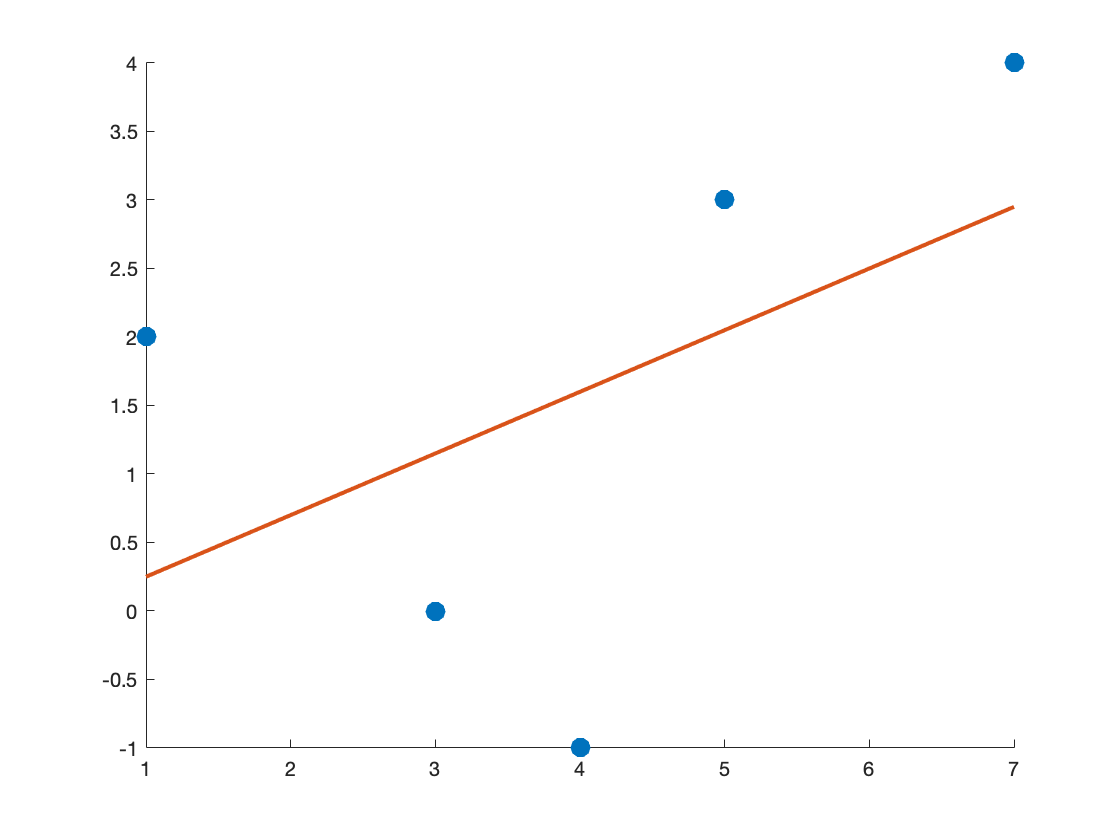


fit = xhat(1) + xhat(2)*A(:,2);
scatter(A(:,2),b,100,'filled')
hold on
plot(A(:,2),fit,'LineWidth',2)
hold off